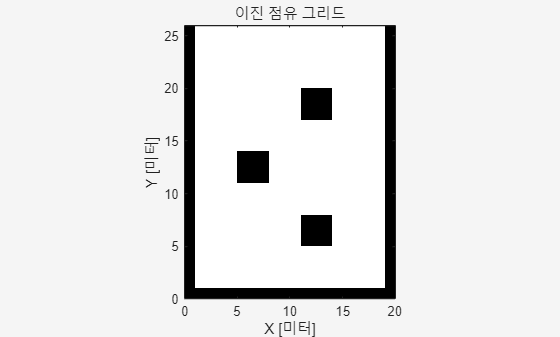

% 1) 원하는 좌표 지정 (행, 열)
obs = [8 13;
       14 7;
       20 13];

% 2) 26×27, 장애물 크기 4셀
binMap = createBinaryMap(26,20, obs, 3);

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(binMap),"Parent",ax);

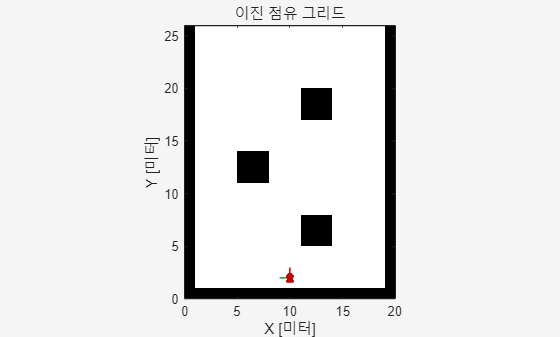


mapMatrix = binMap;
mapScale = 1;

scanAngles = -3*pi/8:pi/8:3*pi/8;
maxRange = 12;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 10;
initY = 2;
initTheta = pi/2;

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

### Environment Interface

Create an environment model that takes the action, and gives the observation and reward signals. Specify the provided example model name, `exampleHelperAvoidObstaclesMobileRobot`, the simulation time parameters, and the agent block name.

mdl = "exampleHelperAvoidObstaclesMobileRobot";
Tfinal = 100;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

Open the model.

open_system(mdl)

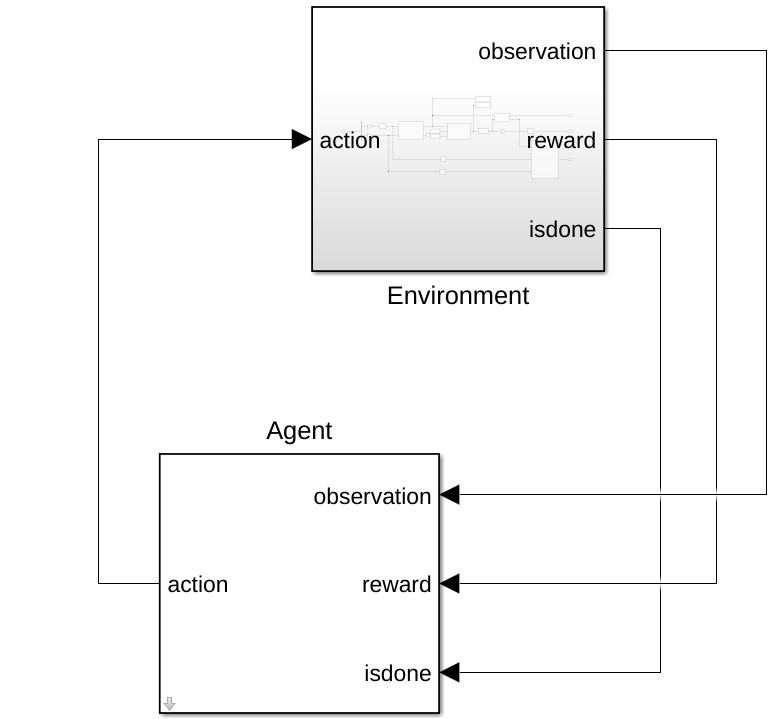

The model contains the `Environment` and `Agent` blocks. The `Agent` block is not defined yet.

Inside the `Environment` Subsystem block, you should see a model for simulating the robot and sensor data. The subsystem takes in the action, generates the observation signal based on the range sensor readings, and calculates the reward based on the distance from obstacles, and the effort of the action commands.

open_system(mdl + "/Environment")

Define observation parameters, `obsInfo`, using the `rlNumericSpec` object and giving the lower and upper limit for the range readings with enough elements for each angular position in the range sensor.

obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);

Define action parameters, `actInfo`. The action is the control command vector, $a = [v , \omega] $, normalized to $[-1, 1]$.

numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);

Build the environment interface object using [`rlSimulinkEnv`](docid:rl_ref.mw_12cc40dc-3191-4a23-af71-1625696c1a14). Specify the model, agent block name, observation parameters, and action parameters. Set the reset function for the simulation using `exampleHelperRLAvoidObstaclesResetFcn`. This function restarts the simulation by placing the robot in a new random location to begin avoiding obstacles. 

env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "Off";

For another example that sets up a Simulink® environment for training, see [Create Simulink Environment and Train Agent](docid:rl_ug.mw_873bd3fc-b713-4e71-b776-9758762d592c).

## DDPG Agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the observation and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);

Next, specify options for the critic optimizer using `rlOptimizerOptions`.

Finally, create the critic representation using the specified deep neural network and options. You must also specify the action and observation specifications for the critic, which you obtain from the environment interface. For more information, see [rlQValueFunction](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Finally, construct the actor in a similar manner as the critic. For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Create the `rlDDPGAgent` object. The `obstacleAvoidanceAgent` variable is used in the model for the `Agent` block.

obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

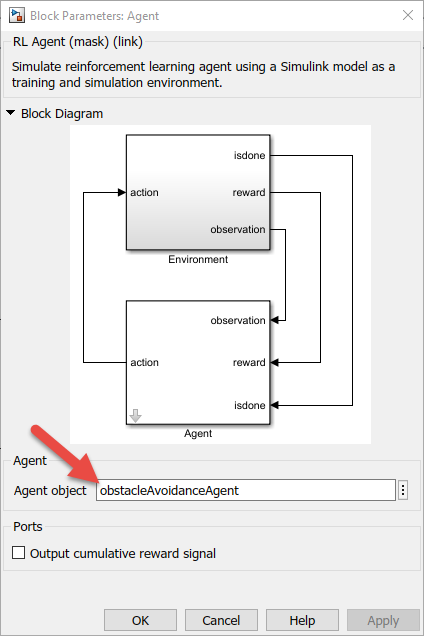

## Reward

The reward function for the agent is modeled as shown.

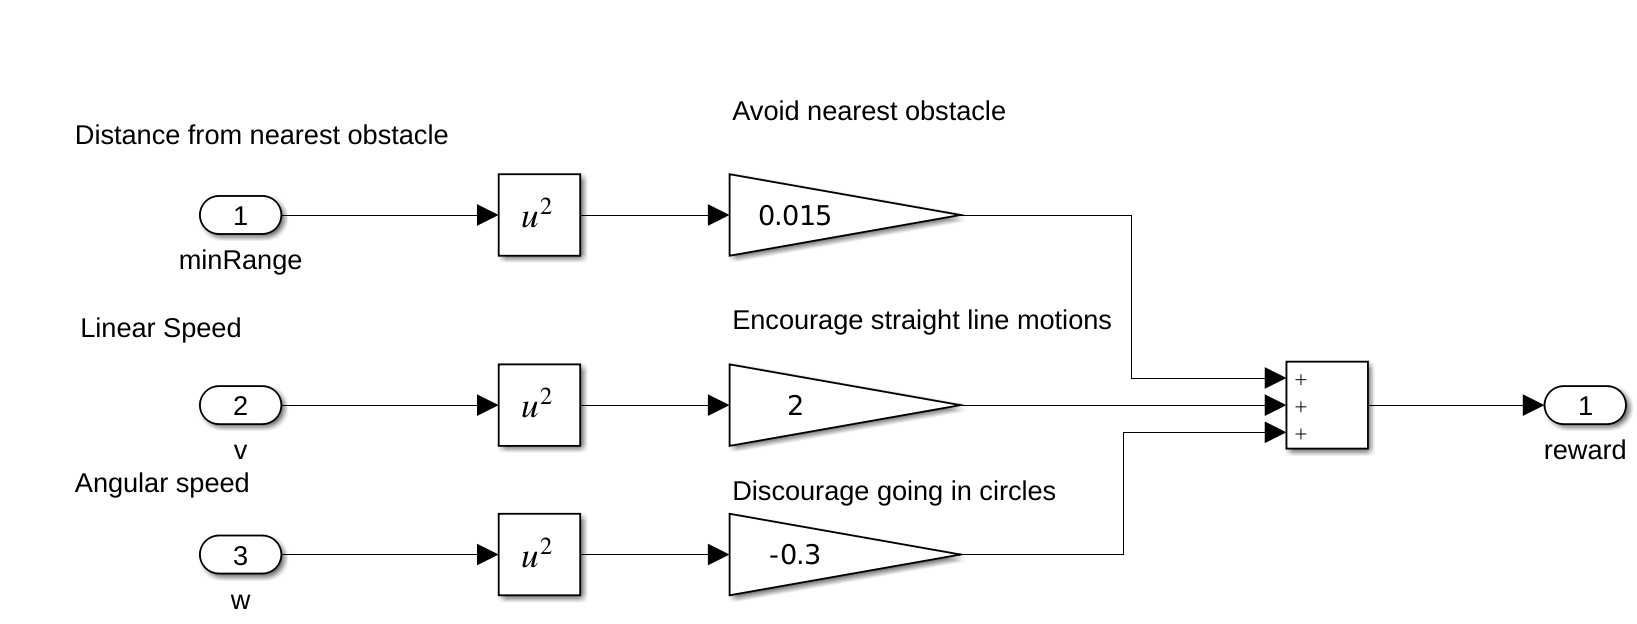

The agent is rewarded to avoid the nearest obstacle, which minimizes the worst-case scenario. Additionally, the agent is given a positive reward for higher linear speeds, and is given a negative reward for higher angular speeds. This rewarding strategy discourages the agent's behavior of going in circles. Tuning your rewards is key to properly training an agent, so your rewards vary depending on your application.

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Train for at most `10000` episodes, with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and enable the command line display (set the `Verbose` option to true).

- Stop training when the agent receives an average cumulative reward greater than 400 over fifty consecutive episodes.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 10000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",400, ...
    "Verbose", true, ...
    "Plots","training-progress");

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally-intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;%true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
end

에피소드:   1/10000 | 에피소드 보상:   294.05 | 에피소드 스텝:  188 | 평균 보상:   294.05 | 스텝 수:  188 | 에피소드 Q0:    59.22
에피소드:   2/10000 | 에피소드 보상:   360.97 | 에피소드 스텝: 1000 | 평균 보상:   327.51 | 스텝 수: 1188 | 에피소드 Q0:    51.13
에피소드:   3/10000 | 에피소드 보상:   461.40 | 에피소드 스텝:  944 | 평균 보상:   372.14 | 스텝 수: 2132 | 에피소드 Q0:    56.26
에피소드:   4/10000 | 에피소드 보상:   264.75 | 에피소드 스텝:  415 | 평균 보상:   345.29 | 스텝 수: 2547 | 에피소드 Q0:    53.27
에피소드:   5/10000 | 에피소드 보상:    77.99 | 에피소드 스텝:  687 | 평균 보상:   291.83 | 스텝 수: 3234 | 에피소드 Q0:    49.51
에피소드:   6/10000 | 에피소드 보상:   478.60 | 에피소드 스텝:  871 | 평균 보상:   322.96 | 스텝 수: 4105 | 에피소드 Q0:    43.99
에피소드:   7/10000 | 에피소드 보상:   303.33 | 에피소드 스텝: 1000 | 평균 보상:   320.16 | 스텝 수: 5105 | 에피소드 Q0:    50.24
에피소드:   8/10000 | 에피소드 보상:     8.38 | 에피소드 스텝:  477 | 평균 보상:   281.18 | 스텝 수: 5582 | 에피소드 Q0:    45.71
에피소드:   9/10000 | 에피소드 보상:   226.72 | 에피소드 스텝: 1000 | 평균 보상:   275.13 | 스텝 수: 6582 | 에피소드 Q0:    53.57
에피소드:  10/10000 | 에피소드 보상:   402.21 | 에피소드 스텝:  582 | 평균 보상:   287.84 | 스

The **Reinforcement Learning Episode Manager** can be used to track episode-wise training progress. As the episode number increases, you want to see an increase in the reward value.

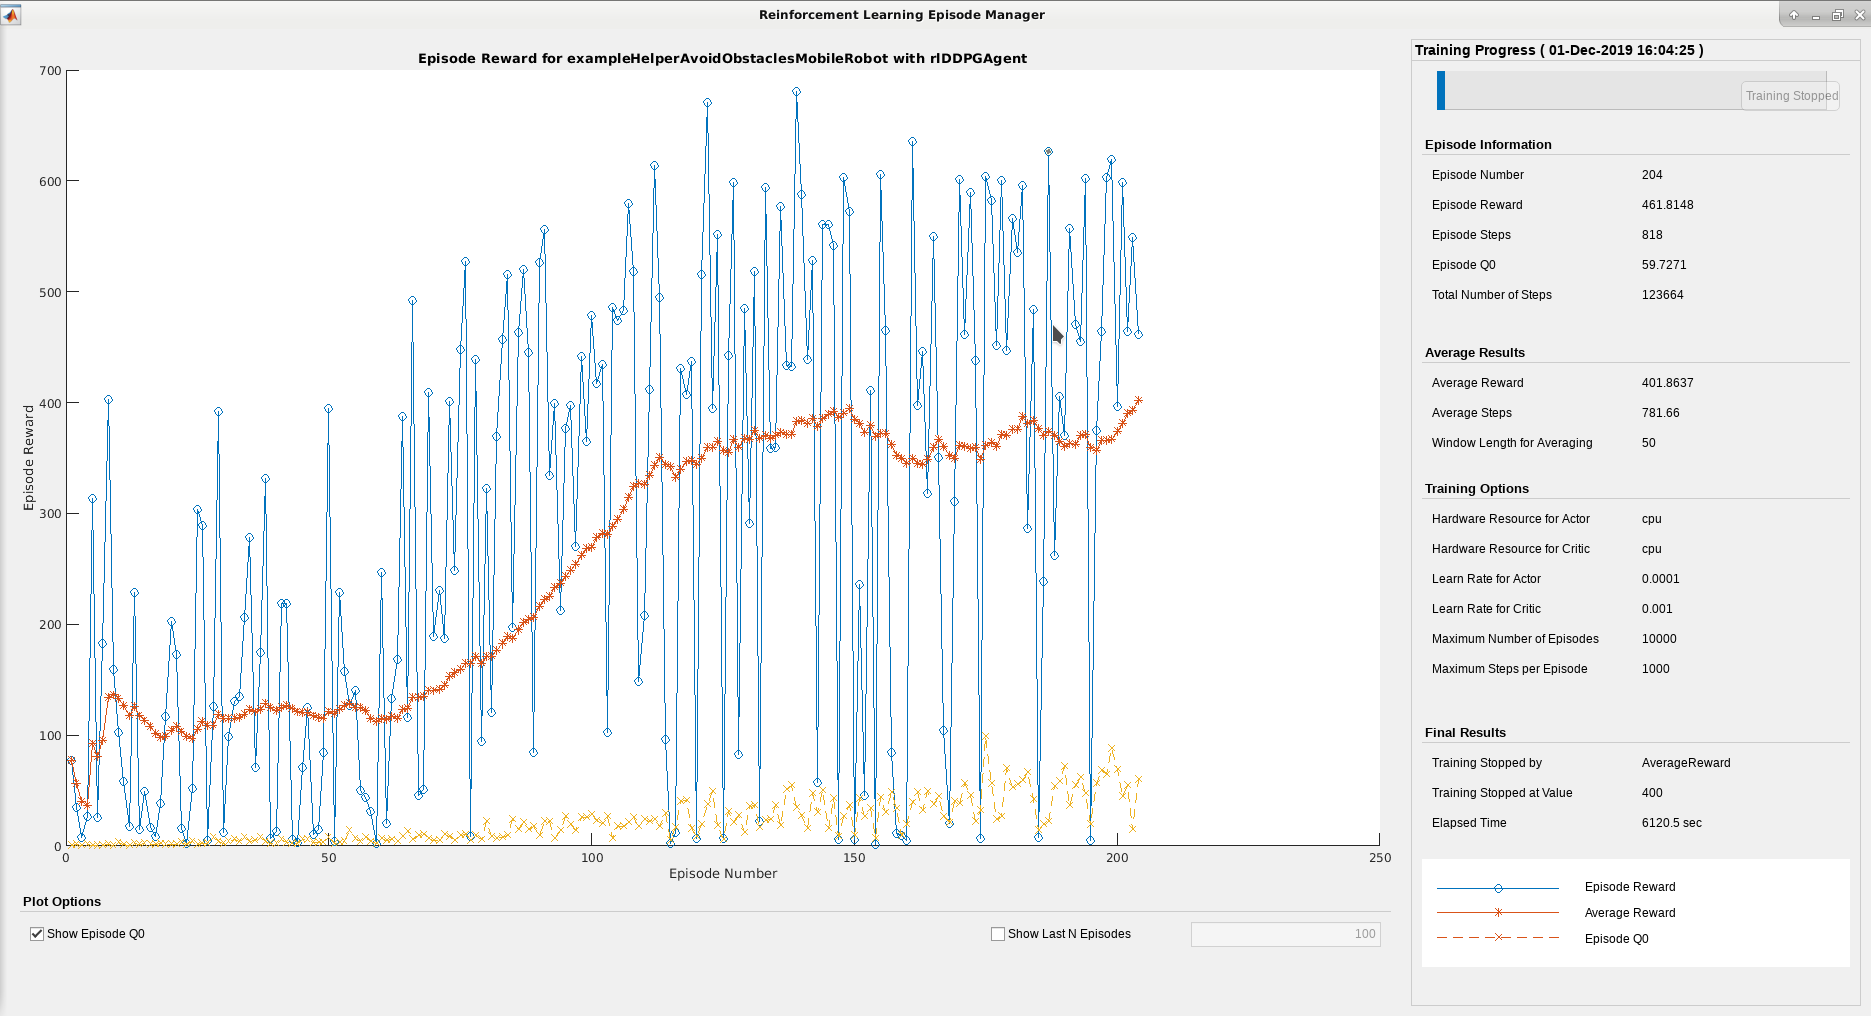

## Simulate

Use the trained agent to simulate the robot driving in the map and avoiding obstacles for 200 seconds. 

% load exampleHelperAvoidObstaclesAgent obstacleAvoidanceAgent
% set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","200");
% out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");

% 1. 에이전트 로드
load("trainedObstacleAvoidanceAgent1.mat", "obstacleAvoidanceAgent");

% 2. 모델 열기
mdl = "exampleHelperAvoidObstaclesMobileRobot";
open_system(mdl);

% 3. Simulink 모델에 에이전트 연결
%    "Agent"라는 이름의 block이 Simulink 안에 있어야 함
%    이 block은 RL Agent 블록이어야 하며,
%    파라미터 "Agent"에 obstacleAvoidanceAgent를 연결
rlAgentBlock = mdl + "/Agent";
set_param(rlAgentBlock, "Agent", "obstacleAvoidanceAgent");

% 4. 시뮬레이션 시간 설정
set_param(mdl, "StopTime", "200");

% 5. 시뮬레이션 실행
out = sim(mdl);


## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

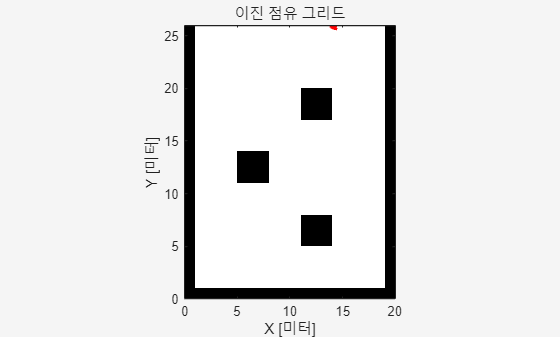

for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
end

## Extensibility

You can now use this agent to simulate driving in a different map. Another map generated from lidar scans of an office environment is used with the same trained model. This map represents a more realistic scenario to apply the trained model after training.

### Change the map

% mapMatrix = office_area_map.occupancyMatrix > 0.5;
% mapScale = 10;
% initX = 20;
% initY = 30;
% initTheta = 0;
% fig = figure("Name","office_area_map");
% set(fig,"Visible","on");
% ax = axes(fig);
% show(binaryOccupancyMap(mapMatrix,mapScale),"Parent",ax);
% hold on
% plotTransforms([initX,initY,0],eul2quat([initTheta, 0, 0]),"MeshFilePath","groundvehicle.stl","View","2D");
% light;
% hold off

### Simulate

Simulate the robot's trajectory across the new map. Reset the simulation time in case the agent needs to be re-trained and retuned later.

% out = sim("exampleHelperAvoidObstaclesMobileRobot.slx");
% set_param("exampleHelperAvoidObstaclesMobileRobot","StopTime","inf");

### Visualize

% for i = 1:5:size(out.range,3)
%     u = out.pose(i,:);
%     r = out.range(:,:,i);
%     exampleHelperAvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
% end

*Copyright 2019-2021 The MathWorks, Inc.*

function binMap = createBinaryMap(nRows, nCols, obsRC, obsSize)
% createBinaryMap  논리형(binary) occupancy 맵 생성
%
%   binMap = createBinaryMap(R, C, OBS) 은
%   • R×C 크기의 false(0) 행렬을 만든 뒤
%   • 왼쪽·아래·오른쪽 경계 = true(1)   (위쪽은 open)
%   • OBS (Mx2 행렬) 위치에 3×3 정사각형 장애물
%   을 추가하여 반환합니다.
%
%   binMap = createBinaryMap(R, C, OBS, SZ) 는
%   SZ(셀) 크기의 정사각형을 추가합니다.
%     - SZ 이 스칼라 → 모든 장애물 동일 크기
%     - SZ 이 M×1 벡터 → 개별 크기
%
%   모든 좌표는 grid index(행, 열) 기준입니다.
%
%   예)
%     obs = [7 10; 13 20; 16 25];
%     M = createBinaryMap(26, 27, obs, 4);
%     imagesc(M); axis equal tight; colormap(gray)

% ---------- 입력검증 ----------
arguments
    nRows   (1,1) {mustBeInteger, mustBePositive}
    nCols   (1,1) {mustBeInteger, mustBePositive}
    obsRC   (:,2) {mustBeInteger, mustBePositive}
    obsSize {mustBeInteger, mustBePositive} = 3
end

if isscalar(obsSize)
    obsSize = repmat(obsSize, size(obsRC,1), 1);
end
assert(numel(obsSize)==size(obsRC,1), ...
    "obsSize must be scalar or length(obsRC) vector.");

% ---------- 기본 맵 ----------
binMap = false(nRows, nCols);

% 왼쪽·아래·오른쪽 벽
binMap(:,1)      = true;   % 왼쪽
binMap(nRows,:)  = true;   % 아래쪽
binMap(:,nCols)  = true;   % 오른쪽
% (원한다면 위쪽도 막으려면 binMap(1,:)=true;)

% ---------- 장애물 삽입 ----------
for k = 1:size(obsRC,1)
    r = obsRC(k,1);
    c = obsRC(k,2);
    sz = obsSize(k);

    half = floor(sz/2);       % 중심 기준 반경
    rIdx = max(r-half,1) : min(r+half, nRows);
    cIdx = max(c-half,1) : min(c+half, nCols);

    binMap(rIdx, cIdx) = true;
end
end
